## Define parameters

N = 100; % number of samples
noiseVar = 2; % Noise Variance of WGN
A = sqrt(20); % DC level component
s = ones(1,N)/sqrt(N); % initialize size for s[n] with DC level unit norm
assert(norm(s) == 1 , 'Norm condition of s[n] is not satisfied');
mcLoops = 1E5;
Matched_H0 = ones(1,mcLoops)*NaN;
Matched_H1 = ones(1,mcLoops)*NaN;

## Running Monte Carlo Loops

for MC = 1 :mcLoops
    noisePart = randn(1,N)*sqrt(noiseVar);
    signalAndNoise = A*s + noisePart;
    % T(x) = x[n]s[n]
    % T(x) for H0 = \Sigma [w[n]s[n]]
    % T(x) for H1 = \Sigma As[n]s[n] + w[n]s[n]
    Matched_H0(MC) = sum(noisePart.*s);
    Matched_H1(MC) = sum(signalAndNoise.*s);
end


## Plotting results

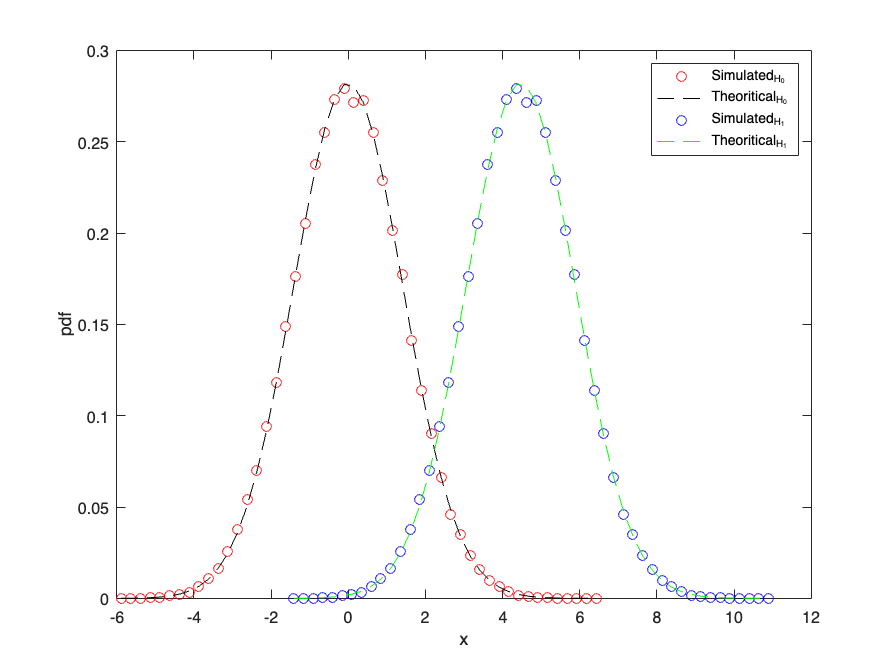

[nH0,xHo] = hist(Matched_H0,50);
[nH1,xH1] = hist(Matched_H1,50);

% Theoretical plot of T(x;H0)
mean_H0 = 0; % Eq(1.8) in the report
var_H0 = noiseVar; % Eq(1.10) in the report
theo_pdf_H0 = 1 / (sqrt(2 * pi * var_H0)) * exp(-((xHo - mean_H0).^2) / (2 * var_H0));
bin_widthH0 = xHo(2) - xHo(1);
plot(xHo,nH0/(sum(nH0)*(bin_widthH0)),'ro',xHo,theo_pdf_H0,'k--')
hold on

% Theoretical plot of T(x;H1)
mean_H1 = A; % Eq(1.9) in the report
var_H1 = noiseVar; % Eq(1.11) in the report
theo_pdf_H1 = 1 / (sqrt(2 * pi * var_H1)) * exp(-((xH1 - mean_H1).^2) / (2 * var_H1));
bin_widthH1 = xH1(2) - xH1(1);
plot(xH1,nH1/(sum(nH1)*(bin_widthH1)),'bo',xH1,theo_pdf_H1,'g--')

legend('Simulated_{H_0}','Theoritical_{H_0}','Simulated_{H_1}','Theoritical_{H_1}');
xlabel('x');
ylabel('pdf')
hold off

## ROC Curves

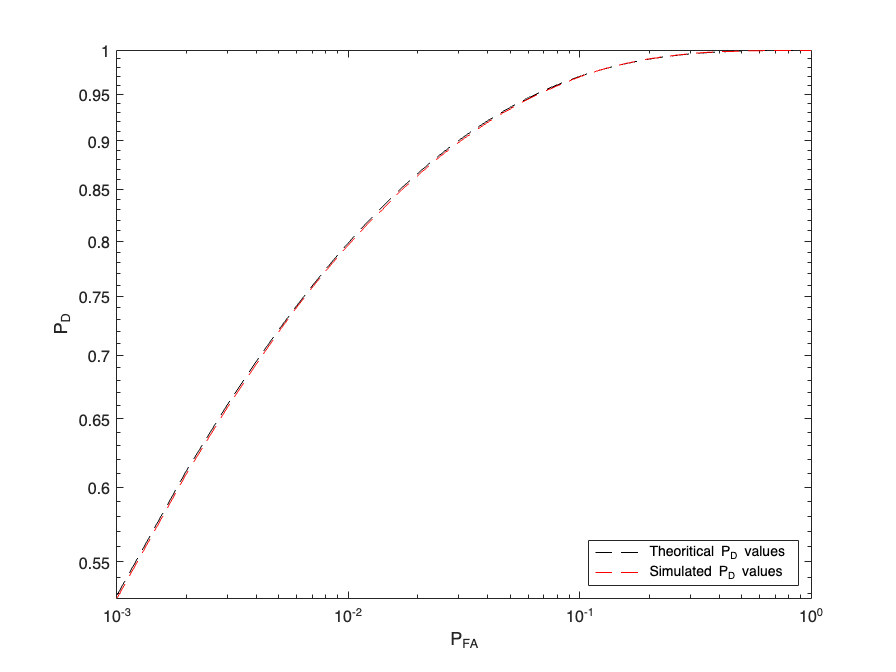

PFA = linspace(0, 1, 1000);
gamma = sqrt(noiseVar)*qfuncinv(PFA); % Eq(1.12) in the report
PD_theo = qfunc((gamma-A)/sqrt(noiseVar)); % Eq(1.13) in the report
PD_simu = ones(size(PFA));

for gammaVal = gamma
    PD_simu(gammaVal == gamma) = mean(Matched_H1 > gammaVal);
end

loglog(PFA,PD_theo,'k--',PFA,PD_simu,'r--')
legend('Theoritical P_D values','Simulated P_D values','Location', 'south east');
xlabel('P_{FA}');
ylabel('P_D')

## Different SNR Values for PD versus PFA curves

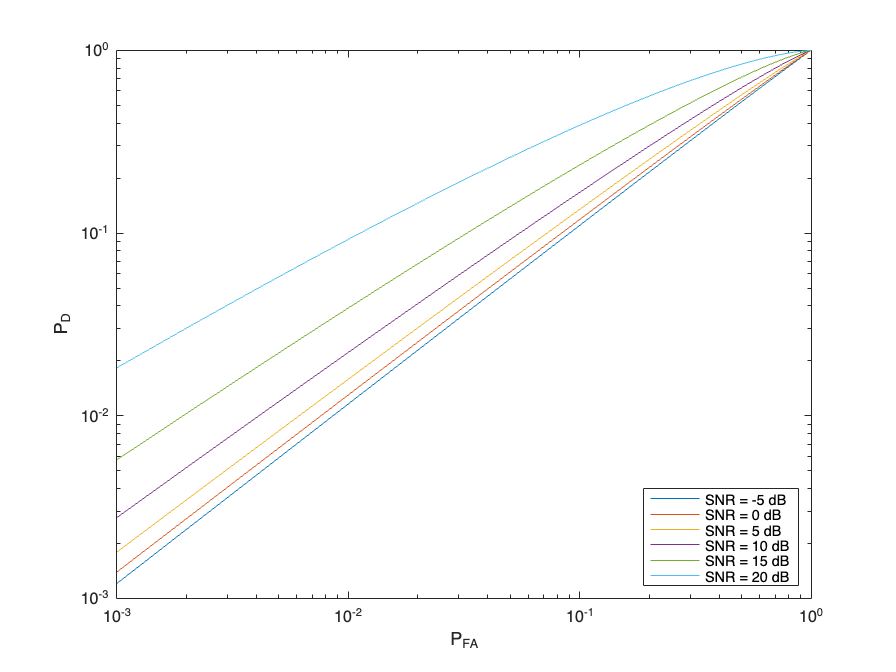

SNRValues = [-5, 0, 5, 10, 15, 20];
AValues = ones(size(SNRValues));

for SNR = SNRValues
    AValues(SNR == SNRValues) = calculate_A(SNR, N, noiseVar);
end



for Aind = AValues
    PD_theo = qfunc((gamma-Aind)/sqrt(noiseVar));
    SNRCoreVal  = SNRValues(Aind ==AValues);
    dispName = ['SNR = ',num2str(SNRCoreVal),' dB'];
    loglog(PFA,PD_theo,'DisplayName', dispName)
    hold on
    
end
hold off
legend('Location', 'south east');
xlabel('P_{FA}');
ylabel('P_D');

function A = calculate_A(SNR_dB, N, noiseVar)
% Function to convert log to linear scale
    SNR_linear = 10^(SNR_dB/10); 
    A = sqrt(SNR_linear * noiseVar / N);
end